clear

addpath("matlab_functions\")

load('data/Sensitivity_100Hz.mat')
lim = 20e-3;

mask = -lim < element_centers(1,:) &  element_centers(1,:) < lim & ...
       -lim < element_centers(2,:) &  element_centers(2,:) < lim;

S = S(:, mask);
element_centers = element_centers(:, mask);

B0 = readmatrix('data/B_defectless.txt');
B0 = B0(:, 2:end).';

B = readmatrix('data/B_defect4.txt');
B = B(:, 2:end).';

delta_B = B - B0;
delta_B = delta_B(:,3);

clear B0 B 

lambda = 1e-20;

beta = 1e-27;
L = speye(size(S,2));
R = decomposition(S' * S + beta * (L' * L));
delta_sigma = zeros(size(S,2), 1);
d = zeros(size(S,2), 1);
b = zeros(size(S,2), 1);

tic
for i = 1:100
    delta_sigma = R \ (S' * delta_B + beta * L' * (d - b));
    d = sthresh(L * delta_sigma + b, lambda/beta);
    b = b + (L * delta_sigma - d);
end
toc

Elapsed time is 2.268470 seconds.



clear lambda beta L R d b i

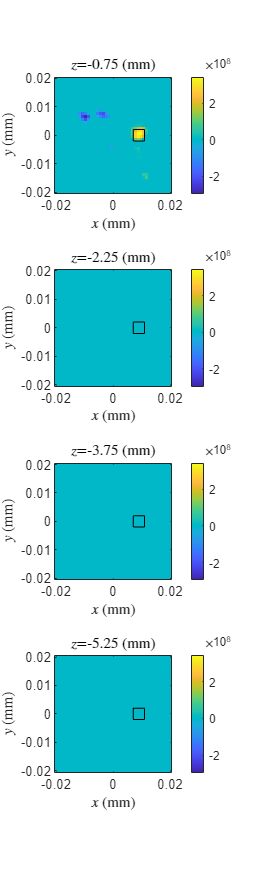

z = unique(element_centers(3,:));
z = sort(z, 'descend');

c = real(-delta_sigma);

figure('Position',[10 10 300 250*length(z)])
for k = 1:length(z)
    mask = element_centers(3,:) == z(k);
    c_layer = reshape(c(mask), sqrt(sum(mask)),[]);

    subplot(length(z),1,k)
    imagesc([-lim lim],[-lim lim], c_layer.', [min(c) max(c)])
    rectangle('Position', [7 -2 4 4] * 1e-3)
    colorbar
    axis square xy
    title(sprintf('$z$=%g (mm)',z(k)*1e3), 'Interpreter','latex')
    xlabel('$x$ (mm)', 'Interpreter','latex')
    ylabel('$y$ (mm)', 'Interpreter','latex')
end


clear lim mask k z c c_layer

function x = sthresh(x, gamma)
xs = abs(x) - gamma;
xs(xs < 0) = 0;
x = xs .* sign(x);
end